## PART 1: KINEMATICS

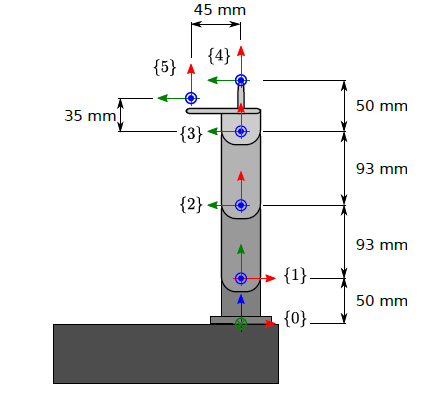

### Problem 1:

Find, by the use of Figure 1, the direct kinematic transformations, $$T_{4}^{0}$$ for the robot stylus, and $$T_{5}^{0}$$ for the robot camera, as function of all joint angles.

% Preliminary transformations

L01 = 50;
L12 = 93;
L23 = 93;
L34 = 50;
L45 = 45;
L35 = 35;

% % Uncomment for symbolic representation
syms theta0 theta1 theta2 theta3 

% Rotation matrices
R_x_90 = [1 0 0;
          0 0 -1;
          0 1 0];
R_z_90 = [0 -1 0;
          1 0 0;
          0 0 1];
R_z_th0 = [cos(theta0) -sin(theta0) 0;
       sin(theta0) cos(theta0) 0;
       0 0 1];
R_z_th1 = [cos(theta1) -sin(theta1) 0;
       sin(theta1) cos(theta1) 0;
       0 0 1];
R_z_th2 = [cos(theta2) -sin(theta2) 0;
       sin(theta2) cos(theta2) 0;
       0 0 1];
R_z_th3 = [cos(theta3) -sin(theta3) 0;
       sin(theta3) cos(theta3) 0;
       0 0 1];

R01 = R_x_90*R_z_th0;
R12 = R_z_90*R_z_th1;
R23 = R_z_th2;
R34 = R_z_th3;
R35 = R_z_th3;

% Translation matrices
t01 = [0 0 L01]';
t12 = [L12 0 0]';
t23 = [L23 0 0]';
t34 = [0 0 L34]';
t35 = [0 0 L35]';

% {0} -> {1}
T01 = [R01 t01;
        zeros(1,3) 1];

% {1} -> {2}
T12 = [R12 t12;
       zeros(1,3) 1];

% {2} -> {3}
T23 = [R23 t23;
       zeros(1,3) 1];

% {3} -> {4}
T34 = [R34 t34;
       zeros(1,3) 1];

% {3} -> {5}
T35 = [R35 t35;
       zeros(1,3) 1];

% Transformation from {0} to {4}
T04 = T01*T12*T23*T34

$$T04 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & \sigma_{1}-\cos\left(\theta_{3}\right)\,\sigma_{3} & 0 & 93\,\cos\left(\theta_{0}\right)-93\,\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)-93\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\\ 0 & 0 & -1 & -50\\ \cos\left(\theta_{3}\right)\,\sigma_{3}-\sigma_{1} & \sigma_{2} & 0 & 93\,\sin\left(\theta_{0}\right)+93\,\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-93\,\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\right)+\sin\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\right)\right)\\ \sigma_{2}=-\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\right)+\sin\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\right)\right)-\sin\left(\theta_{3}\right)\,\sigma_{3}\\ \sigma_{3}=\cos\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\right)-\sin\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\right) \end{array}$$


% Transformation from {0} to {5}
T05 = T01*T12*T23*T35

$$T05 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & \sigma_{1}-\cos\left(\theta_{3}\right)\,\sigma_{3} & 0 & 93\,\cos\left(\theta_{0}\right)-93\,\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)-93\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\\ 0 & 0 & -1 & -35\\ \cos\left(\theta_{3}\right)\,\sigma_{3}-\sigma_{1} & \sigma_{2} & 0 & 93\,\sin\left(\theta_{0}\right)+93\,\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-93\,\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+50\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{3}\right)\,\left(\cos\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\right)+\sin\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\right)\right)\\ \sigma_{2}=-\cos\left(\theta_{3}\right)\,\left(\cos\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\right)+\sin\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\right)\right)-\sin\left(\theta_{3}\right)\,\sigma_{3}\\ \sigma_{3}=\cos\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\right)-\sin\left(\theta_{2}\right)\,\left(\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)\right) \end{array}$$

### Problem 2: 

Determine the inverse kinematic transformation


$$$q = [q_1, q_2, q_3, q_4]^T = f(x_{4}^0, o_{4}^0)$$$


where $$x_{4}^{0}$$ are the first 3 components of the first column of $$T_{4}^{0}$$ , and $$o_{4}^{0}$$ are the first 3 components of the last column of $$T_{4}^{0}$$ , respectively. Satisfy all position components in $$o_{4}^{0}$$ and as many components in $$x_{4}^{0}$$ as possible.

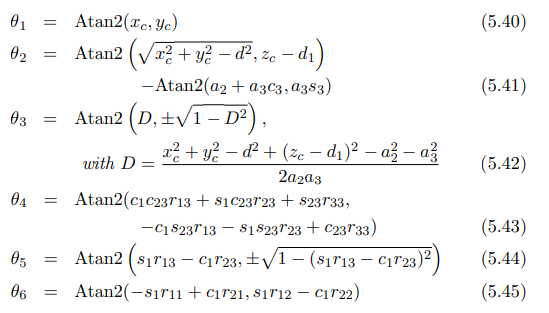

xc = 100;
yc = 100;
zc = 100;


d = L12; % or 23
D = (xc^2 + yc^2 - d^2 + (zc - L01)^2 - L12^2 - L23^2)/(2*L12*L23)

D = -0.1993


% create r

R01 = [1 0 0 0;
       0 cos(theta0) -sin(theta0) 0;
       0 sin(theta0) cos(theta0) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(theta1) -sin(theta1) 0 0;
       sin(theta1) cos(theta1) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;



theta0 = atan2(xc,yc);

theta2 = atan2(D, sqrt(1-D^2));

theta1 = atan2(sqrt(xc^2 + yc^2 - d^2) , zc - L01) - atan2(L12+L23*cos(theta3), L23*sin(theta3));

R01 = [1 0 0 0;
       0 cos(theta0) -sin(theta0) 0;
       0 sin(theta0) cos(theta0) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(theta1) -sin(theta1) 0 0;
       sin(theta1) cos(theta1) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;





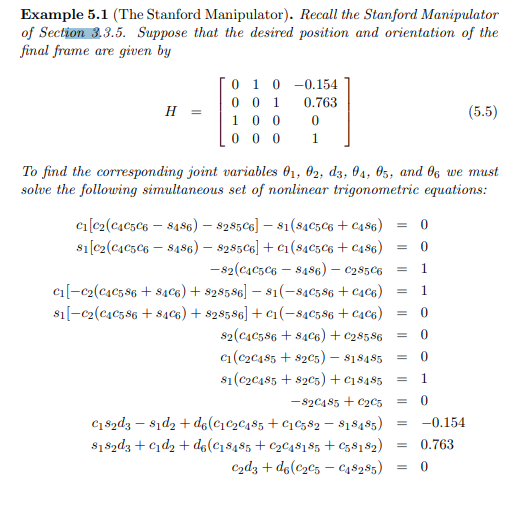

Next up we need to set up and solve this mess of equations.

We have the equations for T04 in the original matrixes calculated from the symbolic variables and we can derive the absolute value of H from the theta values calculated from the grapically derived equations.

## **Problem 3:**

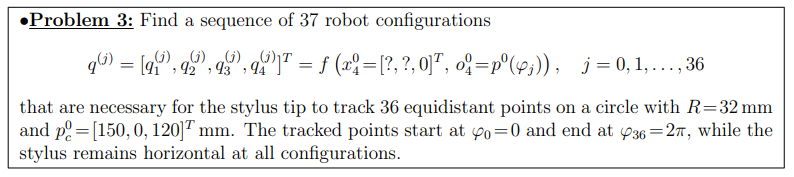


% origin of the circle to be traced
xc = 150;
yc = 100;
zc = 100;

angles = 0:2*pi/36:2*pi % this is the phi angle reported in the previous line

angles =          0    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708    1.7453    1.9199    2.0944    2.2689    2.4435    2.6180    2.7925    2.9671    3.1416    3.3161    3.4907    3.6652    3.8397    4.0143    4.1888    4.3633    4.5379    4.7124    4.8869    5.0615    5.2360    5.4105    5.5851    5.7596    5.9341    6.1087    6.2832




dy = cos(angles)*16;
dz = sin(angles)*16;

x = zeros(1,length(angles))

x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y = yc + dy

y =   116.0000  115.7569  115.0351  113.8564  112.2567  110.2846  108.0000  105.4723  102.7784  100.0000   97.2216   94.5277   92.0000   89.7154   87.7433   86.1436   84.9649   84.2431   84.0000   84.2431   84.9649   86.1436   87.7433   89.7154   92.0000   94.5277   97.2216  100.0000  102.7784  105.4723  108.0000  110.2846  112.2567  113.8564  115.0351  115.7569  116.0000


z = zc + dz

z =   100.0000  102.7784  105.4723  108.0000  110.2846  112.2567  113.8564  115.0351  115.7569  116.0000  115.7569  115.0351  113.8564  112.2567  110.2846  108.0000  105.4723  102.7784  100.0000   97.2216   94.5277   92.0000   89.7154   87.7433   86.1436   84.9649   84.2431   84.0000   84.2431   84.9649   86.1436   87.7433   89.7154   92.0000   94.5277   97.2216  100.0000



[t1,t2,t3] = theta(x,y,z)

t1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


t2 =    -0.7535   -0.7679   -0.7870   -0.8107   -0.8383   -0.8695   -0.9038   -0.9405   -0.9789   -1.0184   -1.0580   -1.0970   -1.1342   -1.1688   -1.1995   -1.2252   -1.2447   -1.2569   -1.2603   -1.2533   -1.2338   -1.2001   -1.1538   -1.0994   -1.0421   -0.9860   -0.9338   -0.8870   -0.8464   -0.8124   -0.7852   -0.7646   -0.7504   -0.7425   -0.7405   -0.7443   -0.7535


t3 =    -0.6158   -0.5996   -0.5909   -0.5897   -0.5961   -0.6099   -0.6310   -0.6591   -0.6937   -0.7343   -0.7805   -0.8315   -0.8867   -0.9452   -1.0062   -1.0686   -1.1308   -1.1909   -1.2455   -1.2899   -1.3173   -1.3213   -1.3007   -1.2608   -1.2088   -1.1500   -1.0882   -1.0257   -0.9641   -0.9047   -0.8483   -0.7959   -0.7482   -0.7058   -0.6692   -0.6391   -0.6158



t4 = ones(1,length(x)).*(pi-t1-t2-t3) % ensures horizontality

t4 =     4.5109    4.5091    4.5195    4.5420    4.5760    4.6211    4.6764    4.7411    4.8142    4.8943    4.9801    5.0700    5.1625    5.2556    5.3473    5.4354    5.5172    5.5894    5.6475    5.6849    5.6927    5.6630    5.5961    5.5018    5.3925    5.2776    5.1636    5.0542    4.9521    4.8587    4.7751    4.7021    4.6402    4.5898    4.5514    4.5250    4.5109



% R01 = [1 0 0 0;
%        0 cos(t1) -sin(t1) 0;
%        0 sin(t1) cos(t1) 0;
%        0 0 0 1];
% % {1} -> {2}
% R12 = [cos(t2) -sin(t2) 0 0;
%        sin(t2) cos(t2) 0 0;
%        0 0 1 0;
%        0 0 0 1];
% 
% R = R01*R12;
% 
% 
% t4 =atan2(cos(t1).*cos(t2+t3).*R(1,3) + sin(t1).*cos(t2+t3).*R(2,3) + sin(t2+t3).*R(3,3), -cos(t1).*sin(t2+t3).*R(1,3) - sin(t1).*sin(t2+t3).*R(2,3)+cos(t2+t3).*R(3,3));


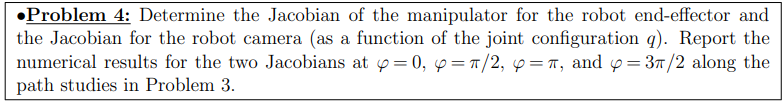

% if you need help figuring out the angles contact Palli
clc
disp("helloo")

helloo


phi = [0 pi/2 pi 3*pi/2];
%phi = pi;
dy = cos(phi)*16;
dz = sin(phi)*16;

x = zeros(1,length(phi));
y = yc + dy;
z = zc + dz;

[t1,t2,t3] = theta(x,y,z);
t4 = ones(1,length(x)).*(pi-t1-t2-t3);

for i = 1:1%length(t1)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));
    J = Jacob(T01, T12, T23, T34)
end

T04 =     0.7293    0.6842         0  197.2877
   -0.6842    0.7293         0  -97.8421
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 =     0.7293    0.6842         0  160.8235
   -0.6842    0.7293         0  -63.6316
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 =     0.7293    0.6842         0   93.0000
   -0.6842    0.7293         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


T01 =      1     0     0     0
     0     1     0     0
     0     0     1    50
     0     0     0     1


z1 =      0     0     1


o1 =      0     0    50


z2 =      0     0     1


o2 =     93     0    50


z3 =      0     0     1


o3 =   160.8235  -63.6316   50.0000


o4 =   197.2877  -97.8421   50.0000


J0 =      0
     0
     1
     0
     0
     0


J1 =    97.8421
  197.2877
         0
         0
         0
    1.0000


J2 =    97.8421
  104.2877
         0
         0
         0
    1.0000


J3 =    34.2105
   36.4642
         0
         0
         0
    1.0000


J =          0   97.8421   97.8421   34.2105
         0  197.2877  104.2877   36.4642
    1.0000         0         0         0
         0         0         0         0
         0         0         0         0
         0    1.0000    1.0000    1.0000


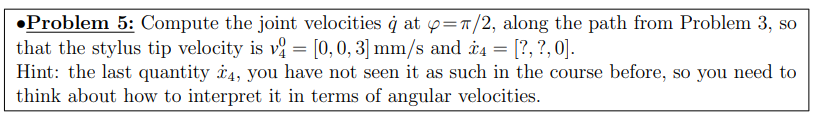

%[T01_old, T12_old, T23_old, T34_old, T35_old] = T_finder(t1(1),t2(1),t3(1),t4(1));

for i = 2:3%length(t1)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));

    T04=T01*T12*T23*T34
    T03=T01*T12*T23
    T02=T01*T12
    
    o4 = [T04(1,4) T04(2,4) T04(3,4)];

    dt1 = t1(i) - t1(i-1);
    dt2 = t2(i) - t2(i-1);
    dt3 = t3(i) - t3(i-1);
    dt4 = t4(i) - t4(i-1);

    k1 = [T01(1,4); T01(2,4); T01(3,4)];
    k1 = k1*(1/max(k1));
    k2 = [T12(1,4); T12(2,4); T12(3,4)];
    k2 = k2*(1/max(k2));
    k3 = [T23(1,4); T23(2,4); T23(3,4)];
    k3 = k3*(1/max(k3));
    k4 = [T34(1,4); T34(2,4); T34(3,4)];
    k4 = k4*(1/max(k4));

    w01 = dt1*k1;
    w12 = dt2*k2;
    w23 = dt3*k3;
    w34 = dt4*k4;

    R01 = [T01(1,1) T01(1,2) T01(1,3);T01(2,1) T01(2,2) T01(2,3);T01(3,1) T01(3,2) T01(3,3)];
    R02 = [T02(1,1) T02(1,2) T02(1,3);T02(2,1) T02(2,2) T02(2,3);T02(3,1) T02(3,2) T02(3,3)];
    R03 = [T03(1,1) T03(1,2) T03(1,3);T03(2,1) T03(2,2) T03(2,3);T03(3,1) T03(3,2) T03(3,3)];
    R04 = [T04(1,1) T04(1,2) T04(1,3);T04(2,1) T04(2,2) T04(2,3);T04(3,1) T04(3,2) T04(3,3)];

    w04 = w01 + R01*w12 + R02*w23 + R03*w34;

    v04 = cross(w04,o4)
    




end

T04 =     0.5248    0.8512         0  168.0413
   -0.8512    0.5248         0 -121.7284
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 =     0.5248    0.8512         0  141.8031
   -0.8512    0.5248         0  -79.1660
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 =     0.5248    0.8512         0   93.0000
   -0.8512    0.5248         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


k1 =      0
     0
     1


k2 =      1
     0
     0


k3 =      1
     0
     0


k4 =      1
     0
     0


v04 =   -11.2721    6.2930   53.2045


T04 =     0.3055    0.9522         0  136.6872
   -0.9522    0.3055         0 -136.1632
         0         0    1.0000   50.0000
         0         0         0    1.0000


T03 =     0.3055    0.9522         0  121.4119
   -0.9522    0.3055         0  -88.5537
         0         0    1.0000   50.0000
         0         0         0    1.0000


T02 =     0.3055    0.9522         0   93.0000
   -0.9522    0.3055         0         0
         0         0    1.0000   50.0000
         0         0         0    1.0000


k1 =      0
     0
     1


k2 =      1
     0
     0


k3 =      1
     0
     0


k4 =      1
     0
     0


v04 =   -11.5201    8.4023   54.3746


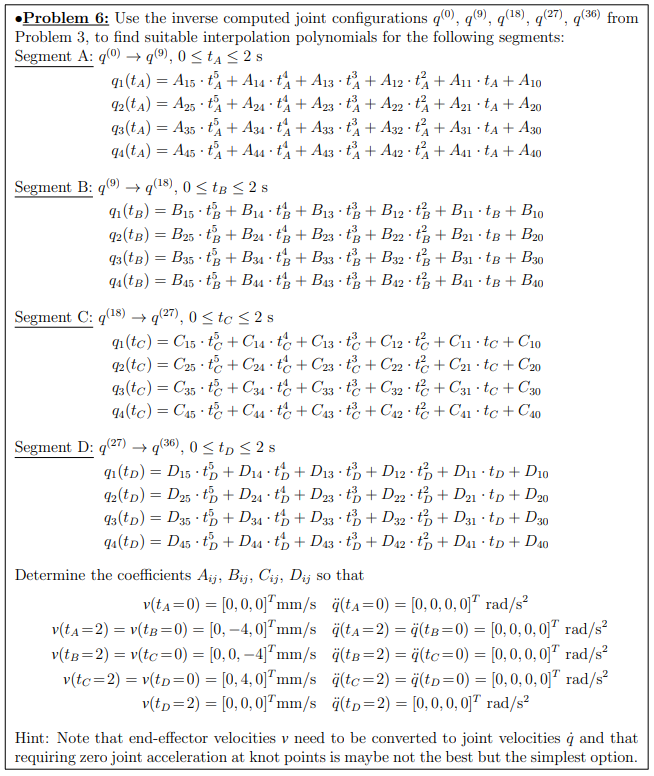

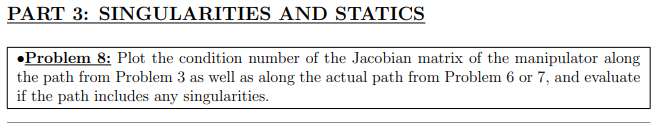

% this uses the collection of angles from problem 3
len = length(t1)
torque2 = zeros(1,len)
torque3 = zeros(1,len)
torque4 = zeros(1,len)

for i=1:len
    [torque2(i),torque3(i),torque4(i)] = torques(t2(i),t3(i),t4(i))
end

figure
plot(t2,torque2)
figure
plot(t3,torque3)
figure
plot(t4,torque4)